# Weka Example 

## initialize weka

javaaddpath('C:\Program Files\Weka-3-8-4\weka.jar','-end')
arffloader = javaObject('weka.core.converters.ArffLoader') %this constructs an object of the arffloader class


arffloader =

weka.core.converters.ArffLoader@2801ccb3



## load up data

arff = javaObject('java.io.File','C:\Program Files\Weka-3-8-4\data\iris.arff') %construct an arff file object


arff =

C:\Program Files\Weka-3-8-4\data\iris.arff



arffloader.setFile(arff)
data = arffloader.getDataSet()


data =

@relation iris

@attribute sepallength numeric
@attribute sepalwidth numeric
@attribute petallength numeric
@attribute petalwidth numeric
@attribute class {Iris-setosa,Iris-versicolor,Iris-virginica}

@data
5.1,3.5,1.4,0.2,Iris-setosa
4.9,3,1.4,0.2,Iris-setosa
4.7,3.2,1.3,0.2,Iris-setosa
4.6,3.1,1.5,0.2,Iris-setosa
5,3.6,1.4,0.2,Iris-setosa
5.4,3.9,1.7,0.4,Iris-setosa
4.6,3.4,1.4,0.3,Iris-setosa
5,3.4,1.5,0.2,Iris-setosa
4.4,2.9,1.4,0.2,Iris-setosa
4.9,3.1,1.5,0.1,Iris-setosa
5.4,3.7,1.5,0.2,Iris-setosa
4.8,3.4,1.6,0.2,Iris-setosa
4.8,3,1.4,0.1,Iris-setosa
4.3,3,1.1,0.1,Iris-setosa
5.8,4,1.2,0.2,Iris-setosa
5.7,4.4,1.5,0.4,Iris-setosa
5.4,3.9,1.3,0.4,Iris-setosa
5.1,3.5,1.4,0.3,Iris-setosa
5.7,3.8,1.7,0.3,Iris-setosa
5.1,3.8,1.5,0.3,Iris-setosa
5.4,3.4,1.7,0.2,Iris-setosa
5.1,3.7,1.5,0.4,Iris-setosa
4.6,3.6,1,0.2,Iris-setosa
5.1,3.3,1.7,0.5,Iris-setosa
4.8,3.4,1.9,0.2,Iris-setosa
5,3,1.6,0.2,Iris-setosa
5,3.4,1.6,0.4,Iris-setosa
5.2,3.5,1.5,0.2,Iris-setosa
5.2,3.4,1.4,0.2,Iris

data.toString


ans =

@relation iris

@attribute sepallength numeric
@attribute sepalwidth numeric
@attribute petallength numeric
@attribute petalwidth numeric
@attribute class {Iris-setosa,Iris-versicolor,Iris-virginica}

@data
5.1,3.5,1.4,0.2,Iris-setosa
4.9,3,1.4,0.2,Iris-setosa
4.7,3.2,1.3,0.2,Iris-setosa
4.6,3.1,1.5,0.2,Iris-setosa
5,3.6,1.4,0.2,Iris-setosa
5.4,3.9,1.7,0.4,Iris-setosa
4.6,3.4,1.4,0.3,Iris-setosa
5,3.4,1.5,0.2,Iris-setosa
4.4,2.9,1.4,0.2,Iris-setosa
4.9,3.1,1.5,0.1,Iris-setosa
5.4,3.7,1.5,0.2,Iris-setosa
4.8,3.4,1.6,0.2,Iris-setosa
4.8,3,1.4,0.1,Iris-setosa
4.3,3,1.1,0.1,Iris-setosa
5.8,4,1.2,0.2,Iris-setosa
5.7,4.4,1.5,0.4,Iris-setosa
5.4,3.9,1.3,0.4,Iris-setosa
5.1,3.5,1.4,0.3,Iris-setosa
5.7,3.8,1.7,0.3,Iris-setosa
5.1,3.8,1.5,0.3,Iris-setosa
5.4,3.4,1.7,0.2,Iris-setosa
5.1,3.7,1.5,0.4,Iris-setosa
4.6,3.6,1,0.2,Iris-setosa
5.1,3.3,1.7,0.5,Iris-setosa
4.8,3.4,1.9,0.2,Iris-setosa
5,3,1.6,0.2,Iris-setosa
5,3.4,1.6,0.4,Iris-setosa
5.2,3.5,1.5,0.2,Iris-setosa
5.2,3.4,1.4,0.2,Iris-

## make a classifier

classifier = javaObject('weka.classifiers.trees.J48')


classifier =

No classifier built



data.setClassIndex(data.numAttributes - 1)
classifier.buildClassifier(data)
classifierc.toString


ans =

J48 pruned tree
------------------

petalwidth <= 0.6: Iris-setosa (50.0)
petalwidth > 0.6
|   petalwidth <= 1.7
|   |   petallength <= 4.9: Iris-versicolor (48.0/1.0)
|   |   petallength > 4.9
|   |   |   petalwidth <= 1.5: Iris-virginica (3.0)
|   |   |   petalwidth > 1.5: Iris-versicolor (3.0/1.0)
|   petalwidth > 1.7: Iris-virginica (46.0/1.0)

Number of Leaves  : 	5

Size of the tree : 	9




## check out the classifier

evaluation = javaObject('weka.classifiers.Evaluation', data)


e =

weka.classifiers.Evaluation@68596992



evaluation.crossValidateModel(classifier, data, 10,...
 javaObject('java.util.Random', 1),...
 javaArray('java.lang.Object',0))
evaluation.toSummaryString


ans =


Correctly Classified Instances         144               96      %
Incorrectly Classified Instances         6                4      %
Kappa statistic                          0.94  
Mean absolute error                      0.035 
Root mean squared error                  0.1586
Relative absolute error                  7.8705 %
Root relative squared error             33.6353 %
Total Number of Instances              150     




## save arff file into matlab readable matrix

saver = javaObject('weka.core.converters.MatlabSaver')


saver =

weka.core.converters.MatlabSaver@361a1e86



saver.setFile(javaObject('java.io.File', 'D:\Armando\LivemRNA\mRNADynamics\src\segmentSpots\ml_segmentation_sandbox\iris.data'))
saver.setInstances(data)
saver.writeBatch
m = load('D:\Armando\LivemRNA\mRNADynamics\src\segmentSpots\ml_segmentation_sandbox\iris.data')

m =     5.1000    3.5000    1.4000    0.2000         0
    4.9000    3.0000    1.4000    0.2000         0
    4.7000    3.2000    1.3000    0.2000         0
    4.6000    3.1000    1.5000    0.2000         0
    5.0000    3.6000    1.4000    0.2000         0
    5.4000    3.9000    1.7000    0.4000         0
    4.6000    3.4000    1.4000    0.3000         0
    5.0000    3.4000    1.5000    0.2000         0
    4.4000    2.9000    1.4000    0.2000         0
    4.9000    3.1000    1.5000    0.1000         0


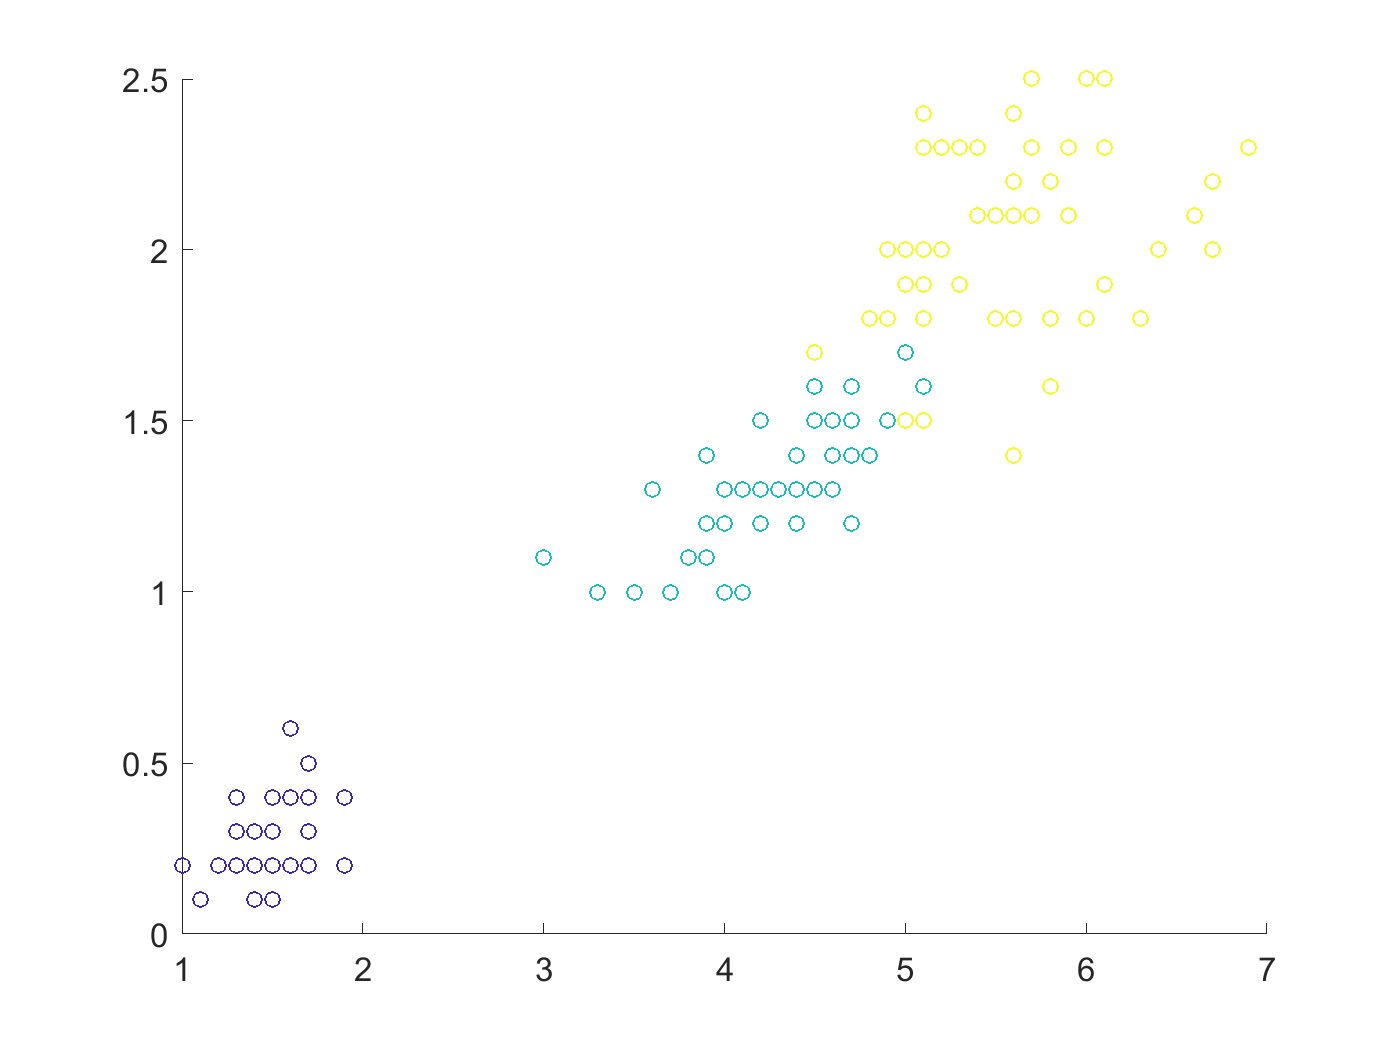

scatter(m(:, 3), m(:, 4), 20, m(:, 5))